clearvars;  
%measurement settings
format shortG
xmin = -5;
xmax = 5;
ymin = -5;
ymax = 5;
zmin = 0;
zmax = 5;
xint = 0.5;
yint = 0.5;
zint = 0.5;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
%datasize = xtotal*ytotal*ztotal;
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 35; %mm

%this is for averaging the measurements at a specific location
% location = [];
% z = zmin;
% dataavg = [];
% 
% for k = 1:ztotal
%     zstr = sprintf('%.1f', z);
%     y = ymin;
% 
%     for j = 1:ytotal
%         ystr = sprintf('%.1f', y);
%         x = xmin;
% 
%         for i = 1:xtotal
% 
%             xstr = sprintf('%.1f', x);
%             filename = append('C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\PIM06152023_magnet4retest\',xstr,'_',ystr,'_',zstr,'.data');
%             test = importdata(filename);
%             
%             bx1 = test.data(1:99,6);
%             by1 = test.data(1:99,7);
%             bz1 = test.data(1:99,8);
% 
%             bx2 = test.data(100:199,6);
%             by2 = test.data(100:199,7);
%             bz2 = test.data(100:199,8);
% 
%             bx3 = test.data(200:299,6);
%             by3 = test.data(200:299,7);
%             bz3 = test.data(200:299,8);
%             
%             bx4 = test.data(300:399,6);
%             by4 = test.data(300:399,7);
%             bz4 = test.data(300:399,8);
%             dataavg = [dataavg 
%                 [mean(bx1) mean(by1) mean(bz1) mean(bx2) mean(by2) mean(bz2) mean(bx3) mean(by3) mean(bz3) mean(bx4) mean(by4) mean(bz4)]];
%             location = [location
%                 [x y z]];
%            
%             x = x + xint;
%         end
%         y = y + yint;
%     end
%     z = z + zint;
% end

% writematrix(dataavg, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06152023_magnet4Raverages.txt');
% writematrix(location, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06152023_magnet4Rlocations.txt')

dataavg = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06152023_magnet4Raverages.txt');
location = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06152023_magnet4Rlocations.txt');

sen1 = dataavg(:,1:3) %bottom left sensor

sen1 =     -0.013997    -0.062867    -0.066148
    -0.014674    -0.062978    -0.066129
     -0.01547    -0.063112    -0.066098
    -0.016282    -0.063157    -0.066149
    -0.017112    -0.063202    -0.066154
    -0.017871    -0.063229    -0.066235
    -0.018874    -0.063319    -0.066132
    -0.019592     -0.06331     -0.06606
    -0.020395    -0.063336    -0.066048
    -0.021264    -0.063247    -0.066043


sen2 = dataavg(:,4:6) %bottom right sensor

sen2 =      0.015993  -0.00058018  -0.00099235
     0.016365  -0.00091529   -0.0011347
     0.016531   -0.0012224   -0.0010951
     0.016754   -0.0016618   -0.0012581
     0.016927   -0.0020423    -0.001186
     0.017171   -0.0022887   -0.0014769
     0.017226   -0.0029036   -0.0014775
     0.017439   -0.0032959    -0.001625
     0.017665   -0.0038143   -0.0017989
     0.017791   -0.0041806   -0.0020036


sen3 = dataavg(:,7:9) %top left sensor (the magnet is centered above this sensor)

sen3 =      0.045494     0.044294      -0.1861
     0.041755     0.044501     -0.18771
     0.037496     0.044715     -0.18927
     0.033303     0.044931     -0.19063
     0.028889     0.045028     -0.19177
     0.024539     0.045127      -0.1968
     0.019819     0.045128     -0.19857
      0.01533     0.045157     -0.19857
     0.010834     0.045141     -0.19857
    0.0062152     0.045143     -0.19857


sen4 = dataavg(:,10:12) %top right sensor

sen4 =      0.032879     0.017431    -0.034741
     0.033888     0.017465    -0.035347
     0.034915     0.017706    -0.036063
     0.035834     0.017792    -0.036755
     0.036863     0.017953    -0.037571
     0.037927     0.018059    -0.038398
     0.038854     0.018123    -0.039298
     0.039894     0.018239    -0.040144
     0.041008     0.018379    -0.041122
     0.042086     0.018503     -0.04214


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 -1], 4851, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =     -0.049256    -0.049256     -0.22517
    -0.044746    -0.049718     -0.22773
    -0.040109    -0.050137     -0.23005
    -0.035357     -0.05051     -0.23213
    -0.030502    -0.050836     -0.23394
    -0.025557    -0.051115     -0.23549
    -0.020538    -0.051345     -0.23677
    -0.015457    -0.051524     -0.23777
    -0.010331    -0.051653     -0.23849
    -0.005173     -0.05173     -0.23892


testB = 2*sen3

testB =      0.090988     0.088589     -0.37219
     0.083509     0.089002     -0.37543
     0.074993      0.08943     -0.37854
     0.066605     0.089863     -0.38125
     0.057778     0.090055     -0.38354
     0.049078     0.090254      -0.3936
     0.039638     0.090257     -0.39713
     0.030661     0.090313     -0.39713
     0.021669     0.090283     -0.39714
      0.01243     0.090287     -0.39714


%fitting for the angle, the sensor is at (0,0,0)
ind = 10;
d_data = sen3;
loc = location + [0 0 35];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =      -0.15691     -0.16839     -0.97315


fval =        11.858


fval/datasize

ans =     0.0024444


sqrt(sum(angle.^2))

ans =             1


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 4851, 1);
faB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

faB =     -0.031453     -0.03008     -0.23515
    -0.026649    -0.030326     -0.23701
    -0.021746    -0.030537     -0.23861
    -0.016758    -0.030712     -0.23995
    -0.011698     -0.03085     -0.24101
   -0.0065811    -0.030949     -0.24179
   -0.0014215     -0.03101     -0.24228
    0.0037655    -0.031032     -0.24249
    0.0089643    -0.031015      -0.2424
      0.01416    -0.030958     -0.24203


expectB

expectB =     -0.049256    -0.049256     -0.22517
    -0.044746    -0.049718     -0.22773
    -0.040109    -0.050137     -0.23005
    -0.035357     -0.05051     -0.23213
    -0.030502    -0.050836     -0.23394
    -0.025557    -0.051115     -0.23549
    -0.020538    -0.051345     -0.23677
    -0.015457    -0.051524     -0.23777
    -0.010331    -0.051653     -0.23849
    -0.005173     -0.05173     -0.23892


fabdiff = expectB - faB

fabdiff =     -0.017803    -0.019177    0.0099776
    -0.018097    -0.019392    0.0092789
    -0.018363    -0.019599    0.0085594
    -0.018599    -0.019798    0.0078209
    -0.018804    -0.019987    0.0070654
    -0.018976    -0.020166    0.0062949
    -0.019116    -0.020334    0.0055116
    -0.019223    -0.020492    0.0047178
    -0.019295    -0.020638    0.0039158
    -0.019333    -0.020773     0.003108


max(fabdiff)

ans =     -0.015158    -0.016532     0.019461


%fitting for the location using the angle from above, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen3(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

%fitting for the angle with 2x measured B, the sensor is at (0,0,0)
% ind = 10;
% d_data = testB;
% loc = location + [0 0 35];
% datasize = length(sen3);
% dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
% nonlcon = @con;
%         
% x0 = [0,0,0];
% A = [];
% b = [];
% Aeq = [];
% beq = [];
% lb = [-1,-1,-1];
% ub = [1,1,1];
% [angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)
% fval/datasize
% sqrt(sum(angle.^2))

% X1 = [0 0 0] - location + [0 0 35];
% R1 = sqrt(sum(X1.^2, 2));
% H_0 = repelem([angle], 4851, 1);
% faB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)
% expectB
% fabdiff = expectB - faB
% max(fabdiff)

%fitting for the location using the angle from above with 2x measured B, the sensor is at (0,0,0)
% fixapreds = [];
% fixafvalues = [];
% for t = 1:length(sen3)
%     B_data = sen3(t,:);
%     costfun = @(v)loccost(v, angle, B_data, B_t);
%     nonlcon = @con;
% 
%     x0 = [-5,-5,35];
%     A = [];
%     b = [];
%     Aeq = [];
%     beq = [];
%     lb = [-20, -20, 30];
%     ub = [20, 20, 60];
%     [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
%     fixapreds = [fixapreds; locs];
%     fixafvalues = [fixafvalues; fval];
% end

% X1 = [0 0 0] - location + [0 0 35];
% R1 = sqrt(sum(X1.^2, 2));
% H_0 = repelem([angle], 4851, 1);
% expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

fixapreds

fixapreds =          -3.78192523785051         -3.48121534238126          37.1163652132958
         -3.28161923089627         -3.48201195236777          37.1486769161646
         -2.71894182510485         -3.49497027549789          37.1843556010048
         -2.17063402462648         -3.50571080299872          37.2111874751782
         -1.60289646896874         -3.50992006309887          37.2427979827916
        -0.983578001086792         -3.37896167331362          37.0457260657634
        -0.389638684976193         -3.34476739795571           37.015408204689
         0.154123611271426         -3.36412458936023          37.0597169869687
         0.701936580815557          -3.3752018586809          37.0900270165213
          1.26754096646193         -3.38482199012435          37.1048241685922


fixafvalues

fixafvalues =       2.23139652101322e-09
      2.55774327221952e-12
      1.16908223949748e-09
      4.43330410738756e-10
      1.43525297553019e-09
      1.71918064950483e-12
      2.59956640725626e-12
      5.90395880959169e-12
      6.64193694059996e-12
      4.00290157272935e-11


fixadiff = fixapreds - loc

fixadiff =           1.21807476214949          1.51878465761874          2.11636521329579
          1.21838076910373          1.51798804763223          2.14867691616457
          1.28105817489515          1.50502972450211          2.18435560100477
          1.32936597537352          1.49428919700128          2.21118747517819
          1.39710353103126          1.49007993690113          2.24279798279161
          1.51642199891321          1.62103832668638          2.04572606576341
          1.61036131502381          1.65523260204429          2.01540820468895
          1.65412361127143          1.63587541063977           2.0597169869687
          1.70193658081556           1.6247981413191          2.09002701652135
          1.76754096646193          1.61517800987565          2.10482416859215


max(fixadiff)

ans =           3.22521112978257          3.39869851554411          4.65282399950991


min(fixadiff)

ans =          0.506227928553344         0.436710596157833          2.01540820468895


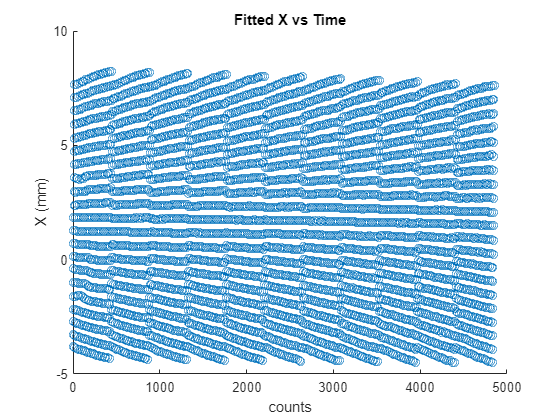

%predicted location using fixed angle
scatter(1:4851,fixapreds(:,1)) %x values
hold on;
title('Fitted X vs Time')
xlabel('counts')
ylabel('X (mm)')
hold off;

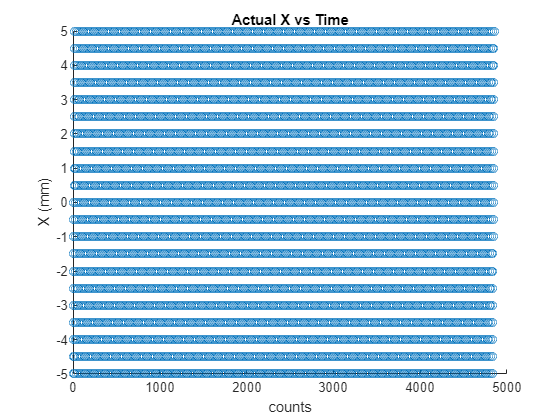


scatter(1:4851,loc(:,1))
hold on;
title('Actual X vs Time')
xlabel('counts')
ylabel('X (mm)')
hold off;

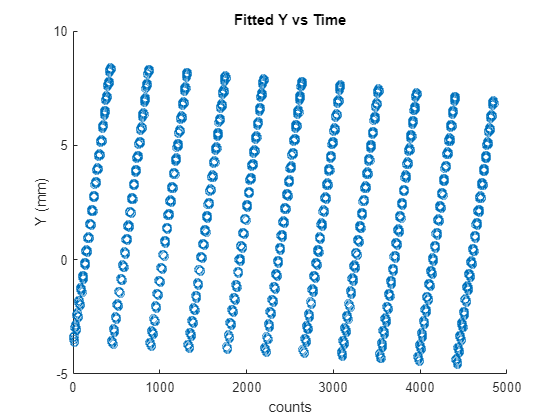



scatter(1:4851,fixapreds(:,2)) %y values
hold on;
title('Fitted Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
hold off;

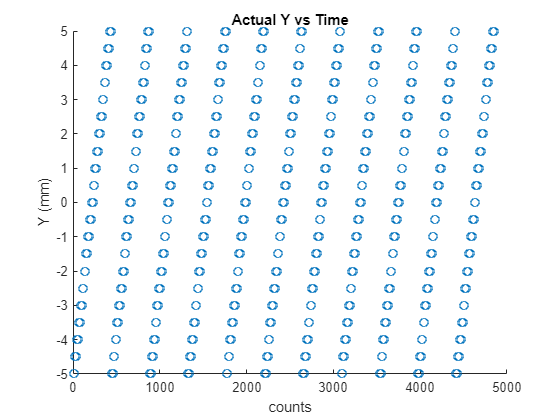


scatter(1:4851,loc(:,2))
hold on;
title('Actual Y vs Time')
xlabel('counts')
ylabel('Y (mm)')
hold off;

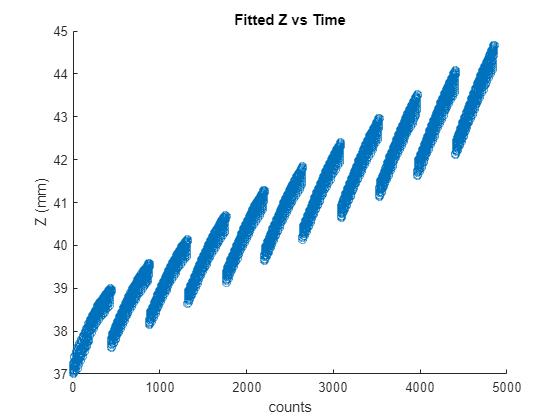


scatter(1:4851,fixapreds(:,3)) %z values
hold on;
title('Fitted Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
hold off;

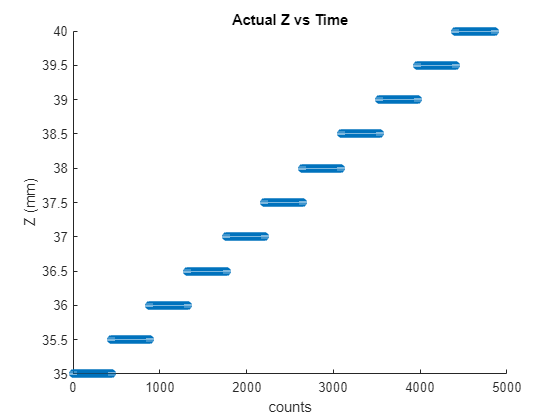

% scatter(1:4851,fixadiff(:,1))
% scatter(1:4851,fixadiff(:,2))
% scatter(1:4851,fixadiff(:,3))

%actual location of measurement


scatter(1:4851,loc(:,3))
hold on;
title('Actual Z vs Time')
xlabel('counts')
ylabel('Z (mm)')
hold off;

testx = sen3 + [0 0 0]

testx =         0.0454941241278002        0.0442944668870119        -0.186095054474232
         0.041754559921655        0.0445012241400416        -0.187713183988248
        0.0374962663728731        0.0447148977843065        -0.189269922879177
        0.0333026686252907        0.0449313869506672        -0.190625535561268
        0.0288887868772188        0.0450276043579386        -0.191769922879177
        0.0245388052393194        0.0451270657363202        -0.196801444485249
        0.0198188884808422        0.0451283510833639        -0.198566960460277
        0.0153303953972334        0.0451565063043212        -0.198565858734239
        0.0108343738523687        0.0451414493818093        -0.198571122536418
       0.00621520381931693         0.045143469212878        -0.198570326845391


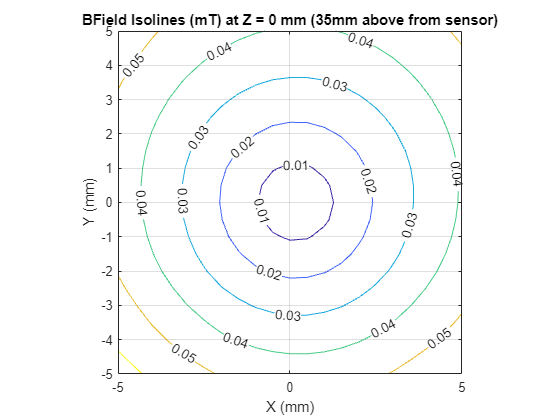

locavg = [location testx];
format longG
zzero = find(abs(locavg(:,3)-0) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;

axis image
grid on;
title('BField Isolines (mT) at Z = 0 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
axis image
hold off

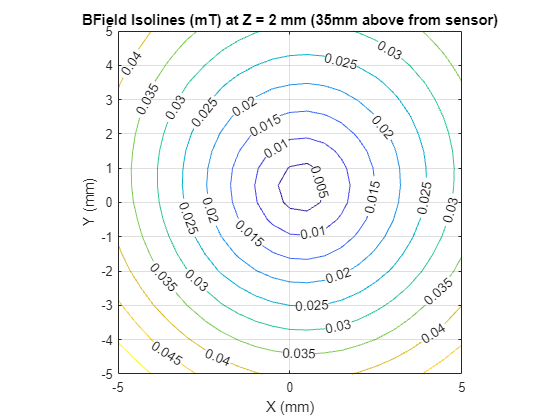

zzero = find(abs(locavg(:,3)-2) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
axis image
grid on;
title('BField Isolines (mT) at Z = 2 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
axis image
hold off

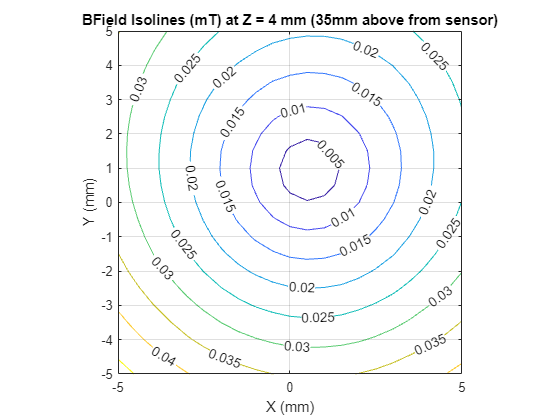

zzero = find(abs(locavg(:,3)-4) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
axis image
grid on;
title('BField Isolines (mT) at Z = 4 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
axis image
hold off

06/06/2023

Meeting Notes

Rotate all sensors and repeat measurement to see if the same stretching happens.

Satwik has circuit board design done and ordered

Sensors are 25mm apart

Maybe try multi sensor with fixed angle (180,000 points) 

Put together Pi and Screen

Stronger magnet, Satwik says he found N55 strength, [https://buymagnets.com/product/neodymium-disc-magnets-n55/](https://buymagnets.com/product/neodymium-disc-magnets-n55/)

Figure out what magnet to buy for next week, look for even stronger magnets

06/13/2023

Test the other N35 magnets for this stretching

check if printer motion is consistent in all three axes

try switching the order of the x and y axes in calibration

measure background

will need to solder sensors onto pcb, look for solder paste and a heat gun.

look for local reseller of bunting magnet, or a way to reduce shipping.

06/20/2023

Try bed leveling and y axis tensioning

Try to limit range of scan: plot -2 to +2. Play around with smaller range of points in the analysis.

Calibrate at different heights.

Do analysis with the four sensor data.

Change meeting time for next month? Maybe MWF afternoons. 

% %fitting for the angle and location, the sensor is at (0,0,0)
% preds = [];
% fvalues = [];
% for t = 1:length(sen3)
%     B_data = sen3(t,:);
%     costfun = @(v)bothcost(v, B_data, B_t);
%     nonlcon = @con;
% 
%     x0 = [0,0,0, -5,-5,35];
%     A = [];
%     b = [];
%     Aeq = [];
%     beq = [];
%     lb = [-1,-1,-1,-7, -7, 0];
%     ub = [1,1,1, 7, 7, 50];
%     [mins, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon);
%     preds = [preds; mins];
%     fvalues = [fvalues; fval];
% end

% anglepred = preds(:,1:3)
% locpred = preds(:,4:6)
% fvalues
% loc
% diff = locpred-loc
% max(diff)
% max(anglepred(:,1))
% max(anglepred(:,2))
% min(anglepred(:,3))

% %predicted location from fitting angle and location
% scatter(1:4851,locpred(:,1)) %x values
% scatter(1:4851,locpred(:,2)) %y values
% scatter(1:4851,locpred(:,3)) %z values
% % scatter(1:4851,fixadiff(:,1))
% % scatter(1:4851,fixadiff(:,2))
% % scatter(1:4851,fixadiff(:,3))
% 
% %actual location of measurement
% scatter(1:4851,loc(:,1))
% scatter(1:4851,loc(:,2))
% scatter(1:4851,loc(:,3))

% scatter(1:4851, sen3(:,1))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,2))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,3))
% hold on;
% grid on;
% xlim([0 100])
% hold off;

function a = anglecost(v, loc, B_data, B_t, datasize)
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t)
X1 = [-x(1) -x(2) -x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end